# Modsim Project 3

## Question

If a penny launcher throws several pennies simulatenously at a piano from a fixed distance, at what angle and speed does each penny need to be thrown in order to play a song on the piano? i.e. such that each penny lands at a different time, in sync with the song?

**Learning Objectives: **As a result of writing this notebook, we (the authors) hope to:

- Increase understanding of optimization

- Increase understanding of physics

- Increase flexibility of code

## Methodology

### Schematic Diagram

### Free Body Diagram

### Stock and Flow

### Mathematical Model

**Parameters**

Penny weight: 2.5g

### Assumptions

### Global Variables/Conversions

### **Verification**

## Results

% for each speed and angle, determine if it will give the correct end x position
% at the point where it reaches y position of the piano (end the simulation at that point)

% after 90 degrees, it's not going to hit the piano no matter what
angle_range = [0:0.25:90]; % degrees
% 37.5 is the speed corresponding to 89.5 degrees
speed_range = [0:0.25:40]; % m/s
% there should one angle for each speed at which the pennies are shot
% that hits the piano (reaches the approximate distance of the x position)
% log the correct 
count = 1;

for i=speed_range
    for j=angle_range
        % ode_penny parameters: (speed in m/s, angle in degrees)
        [T, M, did_hit_piano,end_time] = ode_penny(i,j);
        % sweep angle and speed; there should be one combination of each angle and
        % speed that will get did_hit_piano
        if did_hit_piano
%             uncomment to debug
%             i, j, end_time
            correct_angle_speed_combos(count, 1) = [i];
            correct_angle_speed_combos(count, 2) = [j];
            correct_angle_speed_combos(count, 3) = [end_time];
            count = count + 1;
        end
    end
end
correct_angle_speed_combos

correct_angle_speed_combos =     1.7500   19.0000    0.3025
    1.7500   19.2500    0.3034
    1.7500   19.5000    0.3044
    1.7500   19.7500    0.3053
    1.7500   20.0000    0.3062
    1.7500   20.2500    0.3071
    1.7500   20.5000    0.3080
    1.7500   20.7500    0.3089
    1.7500   21.0000    0.3098
    1.7500   21.2500    0.3108


[T, M, did_hit_piano] = ode_penny(5,16);

end_x_pos = 2.0020

% sweep angle and speed; there should be one combination of each angle and
% speed that will get did_hit_piano
did_hit_piano

did_hit_piano = logical
   1


end_time = 0.4165

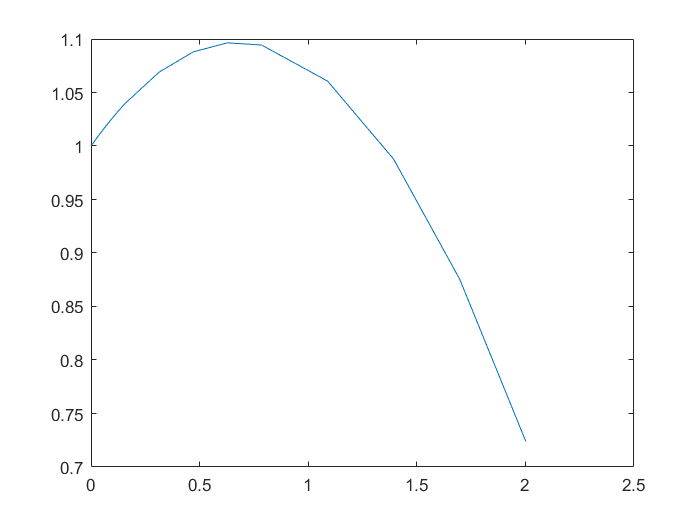

end_time = T(end,1)

X = M(:,1);
Y = M(:,2);
plot(X, Y)

## Interpretation

### **Validation**

### **Model Limitations and Future Development**

## Sources